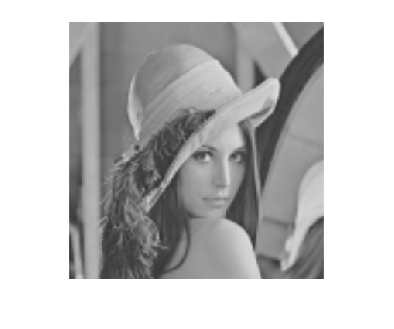

clc;clear all
cm=im2gray(imread('151.jpg'));
imshow(cm)

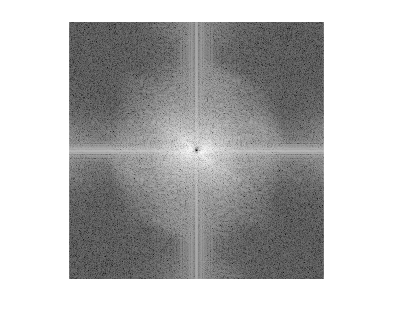

cf=fftshift(fft2(cm));
%fftshow(cf,'log')


%[x,y]=meshgrid(-128:127,-128:127);
[x,y]=meshgrid(-164:164,-165:166);


D=50;
bhh=1-1./(1+((x.^2+y.^2)/D).^2);
cfbh=cf.*bhh;

fftshow(cfbh,'log')

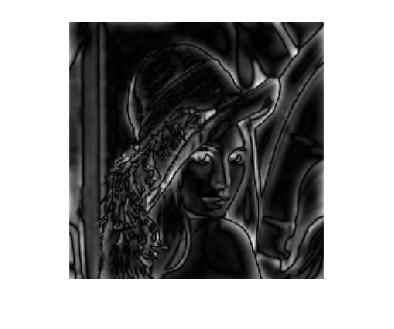

fftshow(ifft2(cfbh),'abs')



hbutter(cm,15,1);
